## Temperature Project (09/02/2021)

The second lab of the Intro to Data Science project looks at a different dataset, being the Hadley Centre Central England Temperature (HadCET) dataset. The dataset contains daily temperature readings from the year 1772, however unlike the Titanic dataset from the last lab, the data is not nicely formatted. This will provide an opportunity for applying preprocessing and data reformatting techniques.

% Note: Run Import_Data.m first to bring data into workspace
% Note: Import_Data.m auto-generated from "Import_Data" button
run('Import_Data.m');
head(cetdl1772on,5)

ans = 5×14 table
    VarName1    VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14
    ________    ________    ________    ________    ________    ________    ________    ________    ________    _________    _________    _________    _________    _________

      1772         1           32         -15          18          25          87         128         187          177          105          111          78  

As can be seen from the table, it does not follow a conventional calendar format. Instead, the following format is adopted:

- First column = Year (1772-2021)

- Second column = Day of month (1-31)

- 3rd-14th column = Data per month of year (Jan/Feb/Mar/.../Oct/Nov/Dec)

While we can keep the data as a table, it is beneficial to convert it into a numeric array, given the prevalence of numeric quantities, and the ease in bulk preprocessing.

data = table2array(cetdl1772on)

data =         1772           1          32         -15          18          25          87         128         187         177         105         111          78         112
        1772           2          20           7          28          38          77         138         154         158         143         150          85          62
        1772           3          27          15          36          33          84         170         139         153         113         124          83          60
        1772           4          27         -25          61          58          96          90         151         160         173         114          60          47
        1772           5          15          -5          68          69         133         146         179         170         173         116          83          50
        1772           6          22         -45          51          77         113         105         175         198         160         134    

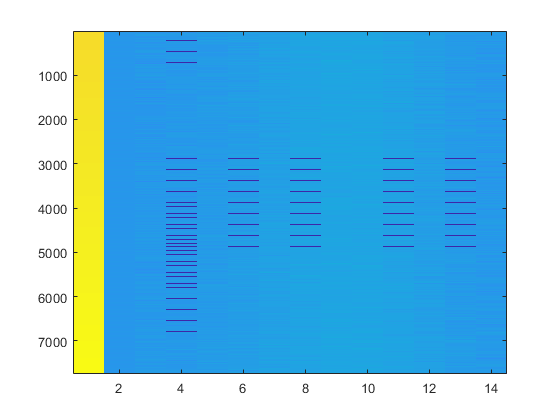

imagesc(data)

Here, we have used the imagesc command to visually interpret the data from the outset. The imagesc command applies a colour range to the array to show the distribution of values. Here, the brighter yellow corresponds to a higher number, which makes sense, becoming brighter as we move down the first column, corresponding to an increasing year, which is much larger than the temperature measurements (which are therefore denoted as blue). Some dark blue bars are evident within the data. These correspond to values of -999 in the data, which are used as placeholders in order to keep a consistent data format despite an alternating number of days in a month for instance - these will subsequently be replaced with NaNs in order to preserve meaning without affecting the remaining data.

Missing data, outliers, and placeholders must be considered and dealt with appropriately during the preprocessing phase. Another important consideration is with respect to the effective units of the dataset - looking at the temperature value for January 1st 1772, we get a value of 32, which intuitively seems high. This is because the results are all multiplied by 10 in order to record values as integers as opposed to floats. So a further preprocessing step of dividing by 10 will be required in order to transform these into their real-world values.

Before continuing, lets do some sense checks with some plots to check data is what we expect it to be.

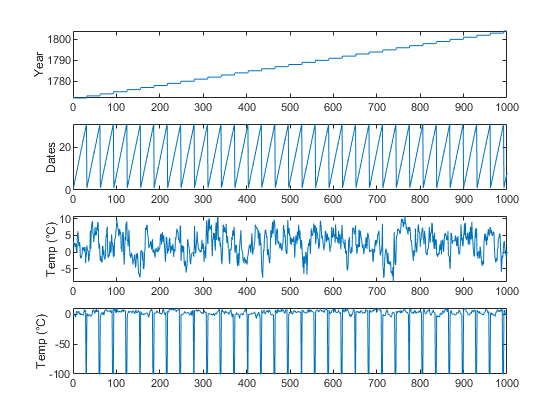

figure
%Years - column 1
subplot(4,1,1);
plot(data(1:1000, 1));
ylabel("Year");

%Dates - column 2
subplot(4,1,2);
plot(data(1:1000, 2));
ylabel("Dates");

%Temperatures - column 3 (January)
subplot(4,1,3);
plot(data(1:1000, 3)/10);
ylabel("Temp (°C)");
%Temperatures - column 4 (February)
subplot(4,1,4);
plot(data(1:1000, 4)/10);
ylabel("Temp (°C)");

These plots appear to make sense. The first plot shows the years, which on the whole appear to be linearly increasing from 1772, as expected (this is in fact stepped, maintaining a consistent value for each 31 rows, but provides an overall linearly increasing trend). The second plot shows the dates, and so follows a sawtooth pattern, incrementing up to 31, and then repeating. The third  and fourth plot show the temperatures across the month of January and February respectively, with the fourth plot particularly highlighting the presence of those placeholder -999 values, being populated at the end of the month, corresponding to the 29th, 30th and 31st, which do not exist for February.

So, out of interest, what would happen if we plotted the mean and median per month with these placeholder values?

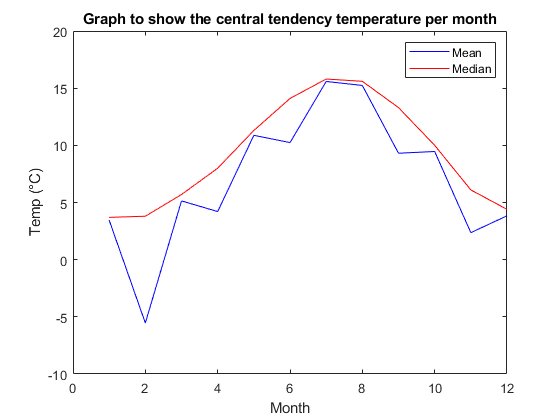

figure;
plot(mean(data(:,3:14)/10), 'blue', "DisplayName","Mean");
hold on;
plot(median(data(:,3:14)/10), 'red', "DisplayName","Median");
ylabel("Temp (°C)");
xlabel("Month");
title("Graph to show the central tendency temperature per month")
legend();
hold off;

Ignoring the placeholder values appears to have had introduced an oscillatory behaviour in the mean curve, highly skewing the monthly temperature. This is because the mean is quite sensitive to outliers (i.e. the placeholder value of -99.9 in this example). In comparison, the median does not appear to be as effected, providing a smoother overall curve.

So lets get rid of these placeholder values, and replace them with NaNs.

% data(find(data==-999)=NaN
data(data==-999)=NaN

data =         1772           1          32         -15          18          25          87         128         187         177         105         111          78         112
        1772           2          20           7          28          38          77         138         154         158         143         150          85          62
        1772           3          27          15          36          33          84         170         139         153         113         124          83          60
        1772           4          27         -25          61          58          96          90         151         160         173         114          60          47
        1772           5          15          -5          68          69         133         146         179         170         173         116          83          50
        1772           6          22         -45          51          77         113         105         175         198         160         134    

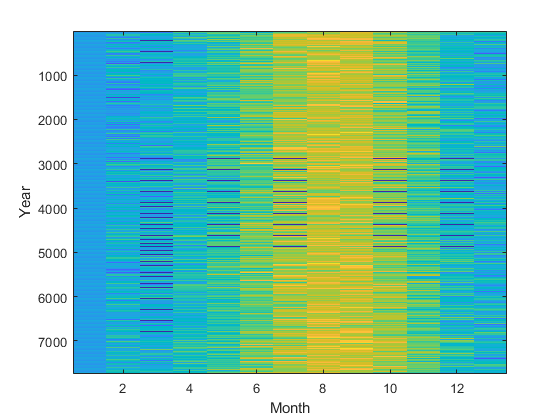

imagesc(data(:,2:14));
ylabel("Year");
xlabel("Month");

Now imagesc is looking much better - the placeholders aren't used for rescaling, so we can now quite distinctly see a seasonal variation for temperature, as would be expected across the year. Some darker bands are still visible, corresponding to the NaNs for the invalid dates. We can make this clearer by reshaping the data.

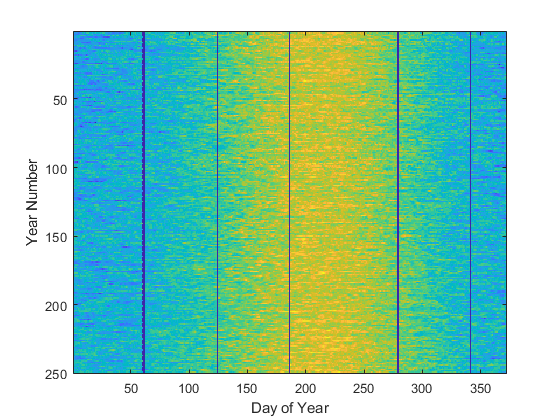

% Extract all unique values from years
years = unique(data(:,1));

% Preallocating calendar_data
calendar_data = zeros(length(years), 31*12);

% Rescaling temperature values
data(:,3:14) = data(:,3:14)/10;

% Iterate through years, convert to vector, and save
for year = 1:length(years)
    year_values = data(data(:,1)==years(year),:);
    reshaped_values = reshape(year_values(:,3:14), 31*12, 1);
    calendar_data(year,:) = reshaped_values;
end

imagesc(calendar_data)
ylabel("Year Number");
xlabel("Day of Year");

This is much better - we can see clear dark blue bands which occur approximately every 60 days, corresponding to the alternating number of days in a month, with a wider dark blue bar around 60, corresponding to February being shorter than the rest, and with a slight dotted effect corresponding to the presence of a leap year every 4 years.

Now using the new, reformatted and preprocessed data, we can have a look at some further plots.

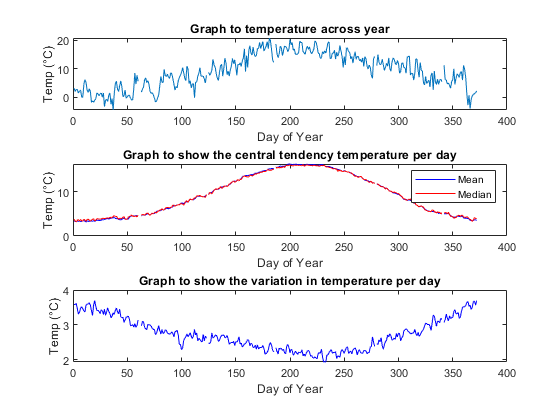

figure;

% Plotting the temperature across the first year (1772)
subplot(3,1,1);
plot(calendar_data(1,:));
ylabel("Temp (°C)");
xlabel("Day of Year");
title("Graph to temperature across year")

% Plotting central tendencies for each day of year
% Note - omitnan is used here with care - not advised in most cases
% (perhaps due to varying operation of omitnan, or false impression the
% data could give if used haphazardly, where imputing may be prefered.
% However, this should be sufficient here for a simply visualisation.
subplot(3,1,2);
plot(mean(calendar_data, 'omitnan'), "blue", "DisplayName", "Mean");
hold on;
plot(median(calendar_data, 'omitnan'), "red", "DisplayName", "Median");
ylabel("Temp (°C)");
xlabel("Day of Year");
title("Graph to show the central tendency temperature per day")
legend();
hold off;

% Plotting variation in daily temperature
subplot(3,1,3);
plot(std(calendar_data, 'omitnan'), "blue");
ylabel("Temp (°C)");
xlabel("Day of Year");
title("Graph to show the variation in temperature per day")

These plots can be used to answer key questions, such as which day has the highest average temperature, or which day's temperature varies the most. The highest temperatures are noted around day 210, corresponding to the middle of the Summer, and the lowest variation in temperature, whereas the lowers temperatures are observed around day 1, corresponding to the middle of the Winter, along with the highest variation in temperature.

We could also reformat the data in a different way. The current format has collapsed the data into a 240x372 dimension matrix, i.e. 372 days (including NaNs) for 240 different years. however, it may be more useful to have a 3D matrix, so that we can index into the different years, months and days. We can do this as follows.

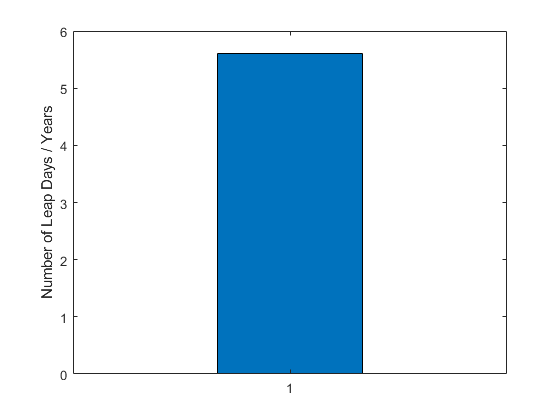

% Preallocate calendar_data_3d
calendar_data_3d = zeros(31, 14, length(year));

% Iterate through and allocate to matrix
for year_counter = 1772:2021
    calendar_data_3d(:,:,year_counter-1771) = (data(data(:,1)==year_counter,:)); 
end

% Conduct sanity check for correct formatting
% e.g. for leap years - counter for how many leap years / leap days
day = 29; month = 2; year = 1773;
leap_day_counter = zeros(1);
for index=1:length(year)
    leap_day_counter(index) = calendar_data_3d(day, month+2, index);
end
% Note: Offsetting by 2, to account for redundant first two
% slices of data (years, days)

figure
bar(leap_day_counter);
ylabel("Number of Leap Days / Years");

Using this new format, we are able to prove sets more easily to answer questions such as what the average temperature in January, in the year 1807, or on the 15th of the month would be. Some examples are given below.

% Finding the average temperature for the 12th month (December)
mean(mean(calendar_data_3d(:,12+2,:),'omitnan'),'omitnan')

ans = 4.2545

% Finding the average temperature for the 7th month (July)
mean(mean(calendar_data_3d(:,7+2,:),'omitnan'),'omitnan')

ans = 16.0498

Now we can generate a time series dataset from this, noting that the NaNs are automatically removed from our dateseries dataset.

%Preallocating vectors
dateseries = zeros((2021-1771)*12*31,1);
tempseries = zeros((2021-1771)*12*31,1);

step = 0;
for year = 1772:2021
    for month = 1:12
        for day = 1:31
            step = step + 1;
            
            % dateseries - vector of dates in single integer form
            dateseries(step) = datenum([year, month, day, 0, 0, 0]);
            
            % tempseries - vector of temperatures
            tempseries(step) = calendar_data_3d(day, month+2, year-1771);
            
        end
    end
end

% Can sanity check our vector format using datestr
datestr(dateseries(1:10))

ans = 10×11 char array
    '01-Jan-1772'
    '02-Jan-1772'
    '03-Jan-1772'
    '04-Jan-1772'
    '05-Jan-1772'
    '06-Jan-1772'
    '07-Jan-1772'
    '08-Jan-1772'
    '09-Jan-1772'
    '10-Jan-1772'


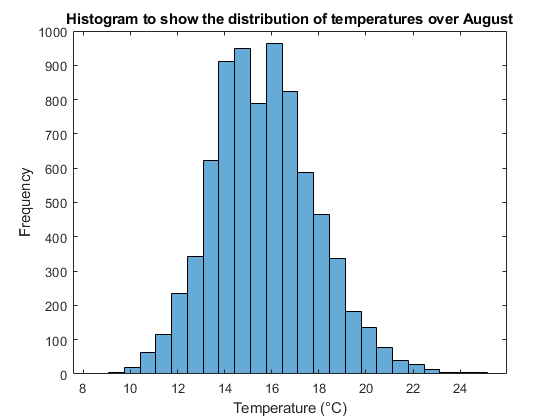

% Plotting a histogram of data over August
dv = datevec(dateseries);
augusts = find(dv(:,2)==8);
figure;
histogram(tempseries(augusts),25);
ylabel("Frequency");
xlabel("Temperature (°C)");
title("Histogram to show the distribution of temperatures over August")

% Computing descriptive statistics per day
% First create set of indices for various months
% Could create sets explicity
jan = find(dv(:,2)==1);
feb = find(dv(:,2)==2);
mar = find(dv(:,2)==3);
apr = find(dv(:,2)==4);
may = find(dv(:,2)==5);
jun = find(dv(:,2)==6);
jul = find(dv(:,2)==7);
aug = find(dv(:,2)==8);
sep = find(dv(:,2)==9);
oct = find(dv(:,2)==10);
nov = find(dv(:,2)==11);
dec = find(dv(:,2)==12);

% Then can calculate average per month (omitnan will suffice for now)
average = [mean(tempseries(jan), 'omitnan'),
            mean(tempseries(feb), 'omitnan'),
            mean(tempseries(mar), 'omitnan'),
            mean(tempseries(apr), 'omitnan'),
            mean(tempseries(may), 'omitnan'),
            mean(tempseries(jun), 'omitnan'),
            mean(tempseries(jul), 'omitnan'),
            mean(tempseries(aug), 'omitnan'),
            mean(tempseries(sep), 'omitnan'),
            mean(tempseries(oct), 'omitnan'),
            mean(tempseries(nov), 'omitnan'),
            mean(tempseries(dec), 'omitnan')];

variation = [std(tempseries(jan), 'omitnan'),
            std(tempseries(feb), 'omitnan'),
            std(tempseries(mar), 'omitnan'),
            std(tempseries(apr), 'omitnan'),
            std(tempseries(may), 'omitnan'),
            std(tempseries(jun), 'omitnan'),
            std(tempseries(jul), 'omitnan'),
            std(tempseries(aug), 'omitnan'),
            std(tempseries(sep), 'omitnan'),
            std(tempseries(oct), 'omitnan'),
            std(tempseries(nov), 'omitnan'),
            std(tempseries(dec), 'omitnan')];

disp(average');

    3.4526    4.0813    5.5602    8.1108   11.3209   14.3651   16.0498   15.6988   13.4025    9.8997    6.1971    4.2545



disp(variation');

    3.4641    3.2240    2.9339    2.7464    2.7646    2.4502    2.2538    2.1848    2.4522    2.8854    3.0751    3.4359



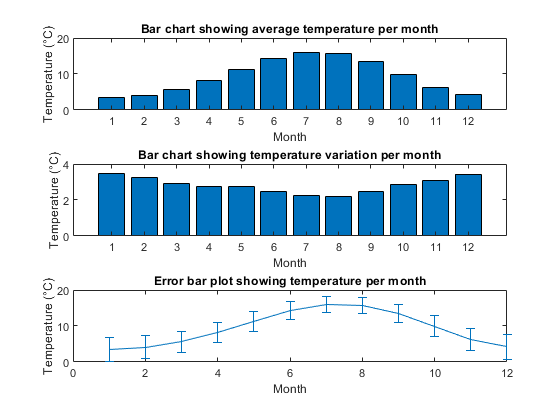

% We can then produce some plots of this data to visualise central
% tendencies and variation (or combination)
figure;
subplot(3,1,1);
bar(average);
ylabel("Temperature (°C)");
xlabel("Month");
title("Bar chart showing average temperature per month")

subplot(3,1,2);
bar(variation);
ylabel("Temperature (°C)");
xlabel("Month");
title("Bar chart showing temperature variation per month")

subplot(3,1,3);
errorbar(average, variation);
ylabel("Temperature (°C)");
xlabel("Month");
title("Error bar plot showing temperature per month")

We could aso plot all monthly histograms of temperatures, or compare a subset. We shall now do so.

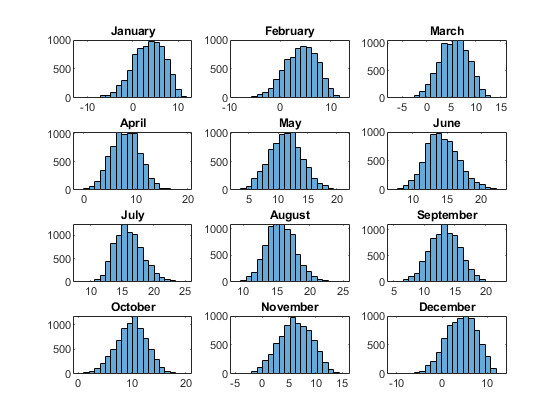

% Plotting histograms of monthly temperatures
figure;
subplot(4,3,1);
histogram(tempseries(jan),20);
title("January");

subplot(4,3,2);
histogram(tempseries(feb),20);
title("February");

subplot(4,3,3);
histogram(tempseries(mar),20);
title("March");

subplot(4,3,4);
histogram(tempseries(apr),20);
title("April");

subplot(4,3,5);
histogram(tempseries(may),20);
title("May");

subplot(4,3,6);
histogram(tempseries(jun),20);
title("June");

subplot(4,3,7);
histogram(tempseries(jul),20);
title("July");

subplot(4,3,8);
histogram(tempseries(aug),20);
title("August");

subplot(4,3,9);
histogram(tempseries(sep),20);
title("September");

subplot(4,3,10);
histogram(tempseries(oct),20);
title("October");

subplot(4,3,11);
histogram(tempseries(nov),20);
title("November");

subplot(4,3,12);
histogram(tempseries(dec),20);
title("December");

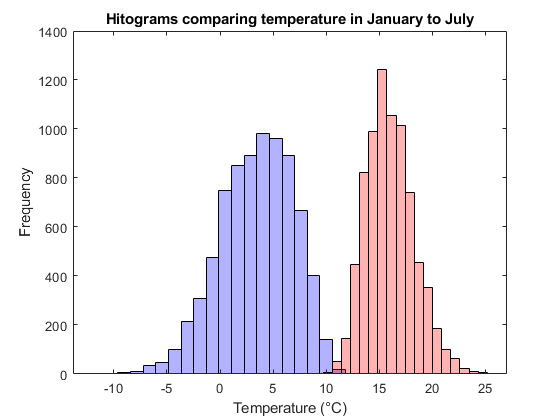

% Comparing Winter to Summer temperatures (January to July)
figure;
histogram(tempseries(jan),20, "EdgeColor","black","FaceColor", ...
    "blue","FaceAlpha",0.3);
hold on;
histogram(tempseries(jul),20, "EdgeColor","black","FaceColor", ...
    "red","FaceAlpha",0.3);
ylabel("Frequency");
xlabel("Temperature (°C)");
title("Hitograms comparing temperature in January to July");
hold off;

Note: for visualisation, it is also possible to create an animated output using Matlab commands "getframe" and "movie".